# Volume Viewer Widget

`VolumeViewer` is intended for displaying a 3D image volume. You can choose the view dimension and the slice to navigate the data.

## Create the widget with the default dataset

f = uifigure;
g = uigridlayout(f,[1 1]);
w = wt.VolumeViewer(g);

### Set the view

w.View = 'xy';
w.Slice = 3;

### Turn on optional axes and grid

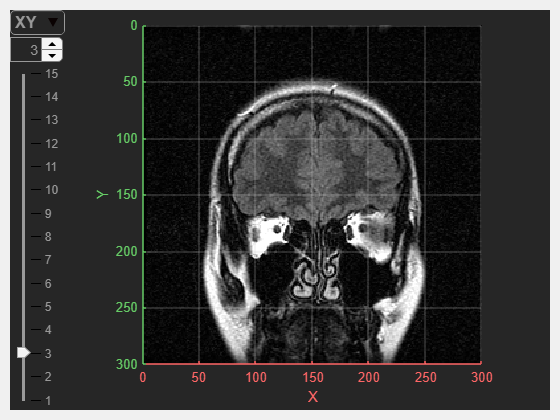

w.ShowAxes = true;
w.ShowGrid = true;

## Load in a DICOM image stack

Specify the DICOM source folder:

dicomFolder = fullfile(matlabroot,"toolbox","images","imdata","dog");

Load the DICOM files into a `VolumeModel` object. The `VolumeModel` contains the image data and related metadata needed for visualization.

volModel = wt.model.VolumeModel.fromDicomFile(dicomFolder);
volModel.Name = 'dog'

volModel =   VolumeModel with properties:

                       Name: 'dog'
                      Alpha: 1
                  ImageData: [512×512×22 int16]
                   DataSize: [3×1 double]
                WorldExtent: [3×2 double]
    WorldExtentPixelCenters: [3×2 double]
                PixelExtent: [3×1 double]
                 PixelEdges: {3×1 cell}
               PixelCenters: {3×1 cell}


*Note: In this example dataset, the Z-slices of the imagery are not uniformly spaced. You will see a warning but can ignore that for the purposes of this example.*

Finally, we can provide the `VolumeModel` to the VolumeViewer widget for it to be displayed.  

w.VolumeModel = volModel;

The DICOM file contains information about the world coordinates. To adjust those, you can edit these properties:

- `WorldExtent`: The coordinate extents of the entire volume from the outermost edges of the first and last pixels in each dimension.

- `WorldExtentPixelCenters`: The coordinate extents of the entire volume from the centers of the first and last pixels in each dimension. (The end pixels partially extend outside the specified range.)

If you set one of these properties, the other will automatically update. It is assumed the pixels are uniformly spaced (`PixelExtent` property) in each individual dimension. This example shows how you might set the `WorldExtent` property:

*Copyright 2018-2021 The MathWorks, Inc.*